%loading my real world dataset.
data = readtable("C:\Users\Ramkumar K R\OneDrive\Desktop\SEM-1 PROJECTS\MFC\diabetes.csv");

% Extracting the  numeric data in the dataset(assuming all columns are numeric)
numericData = data{:, :};

% Standardize the data
numericData = (numericData - mean(numericData)) ./ std(numericData);

% Perform PCA using the inbuild function to reduce data to 2
% dimensions(2d).
[coeff, score, ~, ~, explained] = pca(numericData)

coeff =     0.2160    0.5274    0.1645    0.1609    0.2118   -0.4568    0.0785   -0.5406    0.2651
    0.4368    0.0956   -0.3914   -0.3271    0.1088    0.3827   -0.2080    0.0252    0.5811
    0.3005    0.0463    0.6297    0.0111   -0.0594    0.6079    0.3267   -0.1628   -0.0683
    0.3073   -0.4484    0.2943    0.0740    0.1718   -0.3980    0.2820    0.4349    0.3948
    0.3363   -0.3553   -0.1417   -0.0976    0.6504   -0.0087   -0.0822   -0.2688   -0.4785
    0.3973   -0.2103    0.2519   -0.1632   -0.5275   -0.2410   -0.5725   -0.1665   -0.1264
    0.2376   -0.1752   -0.2853    0.8735   -0.1566    0.1716   -0.0572   -0.0932    0.0496
    0.2787    0.5332    0.1261    0.1711    0.2043    0.0011   -0.2994    0.6149   -0.2888
    0.4157    0.1548   -0.3946   -0.1817   -0.3779   -0.1714    0.5804    0.0683   -0.3176


score =     1.7558    1.1110   -0.2087    0.3335   -0.4814   -0.4327    0.4574    1.1237    0.4936
   -1.5064   -0.5590    0.6502    0.2298    0.0049   -0.1192    0.3662    0.8519    0.0313
    0.6504    1.9283   -2.0064   -0.0261   -0.2339    0.6736    0.7210   -0.7928    1.0630
   -1.5864   -1.0644    0.4741   -0.5803    0.2972   -0.0709    0.3445   -0.0306   -0.2408
    2.4818   -2.3580   -2.9236    3.9340   -1.5653   -0.2003   -0.8146    0.3984   -0.2490
   -1.4427    1.0547    0.2777   -0.4157    0.1453    0.6371    0.0041   -0.6124    0.1816
   -0.5067   -0.6259   -0.3915   -0.4892   -0.4402   -1.6058    1.2210    0.3543   -0.8023
   -1.8674    1.3889   -1.5165   -0.6010    0.0485   -2.7079   -1.7893   -1.0312    0.6768
    3.4935   -0.8620   -1.2148   -1.9023    3.0933    0.1948    0.0307    1.1811   -1.0245
   -0.6137    3.6830   -0.3850    0.2280    1.6195    1.4705    2.8462    0.6582   -0.3364


explained =    26.1389
   19.7146
   12.4469
    9.7995
    9.3847
    8.1652
    5.4269
    4.6465
    4.2768



% Ploting the original data which is reduced using pca.
figure;
scatter(score(:, 1), score(:, 2), 20, 'b', 'filled'); % Original data in blue
hold on;

% Compute the distances from the center (origin) in the 2D PCA space
%setting the thresold values and caluclating the disatance,and marking the
%anamolies
distances = sqrt(sum(score(:, 1:2).^2, 2))

distances =     2.0778
    1.6068
    2.0351
    1.9104
    3.4234
    1.7871
    0.8053
    2.3273
    3.5983
    3.7338



% Define a threshold for anomaly detection (e.g., 95th percentile distance)
threshold = prctile(distances, 95) %Computes Euclidean distances from the origin in the PCA-reduced 2D space.

threshold = 3.4273


% Find indix  of the anomalies,and storing it in a matrix.
anomalies = distances > threshold %Sets a 95th percentile threshold, marking any point beyond this distance as an anomaly.

anomalies = 768×1 logical array
   0
   0
   0
   0
   0
   0
   0
   0
   1
   1


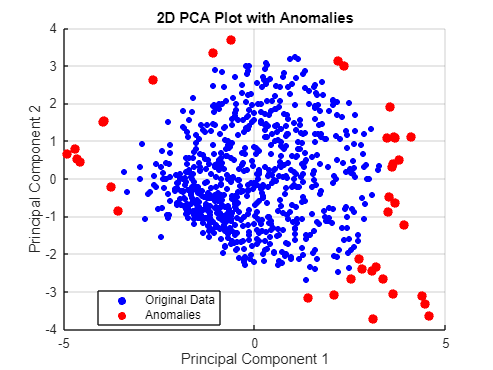


% Plot the anomalies in red and markibg in red.
scatter(score(anomalies, 1), score(anomalies, 2), 50, 'r', 'filled'); % Anomalies in red

% Formatting the plot
xlabel('Principal Component 1');
ylabel('Principal Component 2');
title('2D PCA Plot with Anomalies');
legend({'Original Data', 'Anomalies'}, 'Location', 'best');
grid on;
hold off;